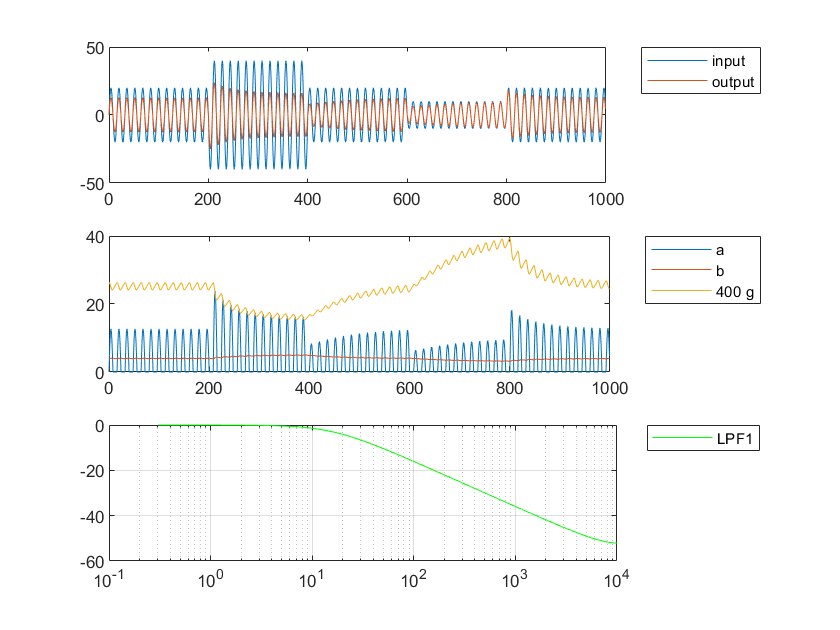

global T;
sr = 20000;    % Sample Rate, Hz
T = 1 / sr;    % Sampling Period, sec

am_sine_freq = 1250;  % Signal Frequency, Hz
am_sine_amp = 20;     % Base Amplitude
am_sine_mf = 2;       % AM Modulation Factor
N = 1000;             % Signal Sample Count
% The first 20 periods are used to prime the AGC, not plotted.
[sine_in, sine_in_start] = am_sine(am_sine_freq, am_sine_amp, am_sine_mf, N, 20);

% Columns of the loop parameters.
global Loop_omega_col Loop_K_col Loop_gain_col;
Loop_omega_col = 1;
Loop_K_col = 2;
Loop_gain_col = 3;

% Columns of the output from the AGC function.
global AGC_y_col AGC_a_col AGC_b_col AGC_g_col;
AGC_y_col = 1;
AGC_a_col = 2;
AGC_b_col = 3;
AGC_g_col = 4;

all_sine_outs = zeros(length(sine_in) - sine_in_start + 1, 5);
fig = 1;

% Trying to replicate Fig. 11.10. H = 10, omega = 1/200, K = -4
% Half-Wave Rectifier
hwr = @(x) (x + abs(x)) / 2;
figure(fig);
all_sine_outs(:, fig) = plot_AGC(sine_in, sine_in_start, 10, hwr, [1 / (sr / 100), -4, 1;]);

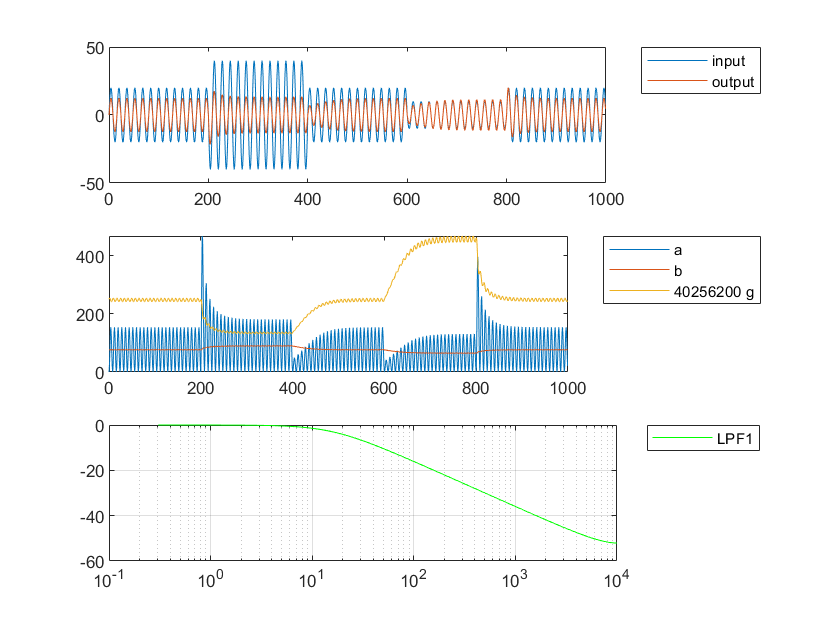

fig = fig + 1;

% Homework: Use square-law detector instead of HWR
sqr_law = @(x) x .* x;
figure(fig);
all_sine_outs(:, fig) = plot_AGC(sine_in, sine_in_start, 100000, sqr_law, [1 / (sr / 100), -4, 1;]);

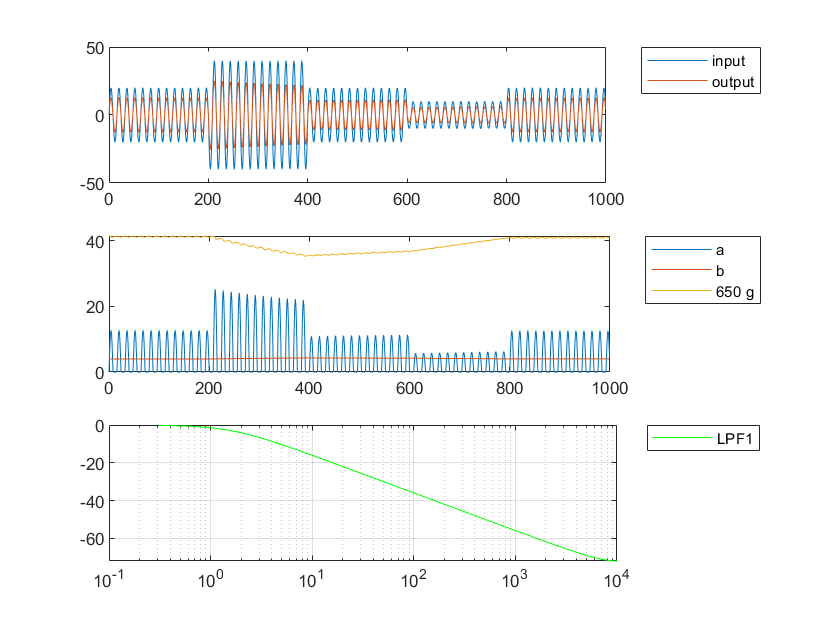

fig = fig + 1;

% Trying a slower filter
figure(fig);
all_sine_outs(:, fig) = plot_AGC(sine_in, sine_in_start, 10, hwr, [1 / (sr / 10), -4, 1;]);

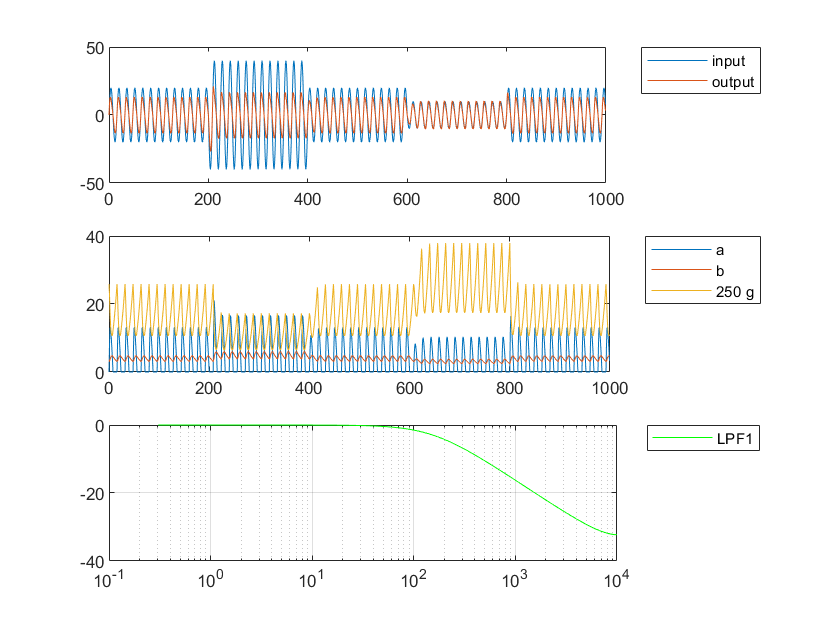

fig = fig + 1;

% Trying a faster filter
figure(fig);
all_sine_outs(:, fig) = plot_AGC(sine_in, sine_in_start, 10, hwr, [1 / (sr / 1000), -4, 1;]);

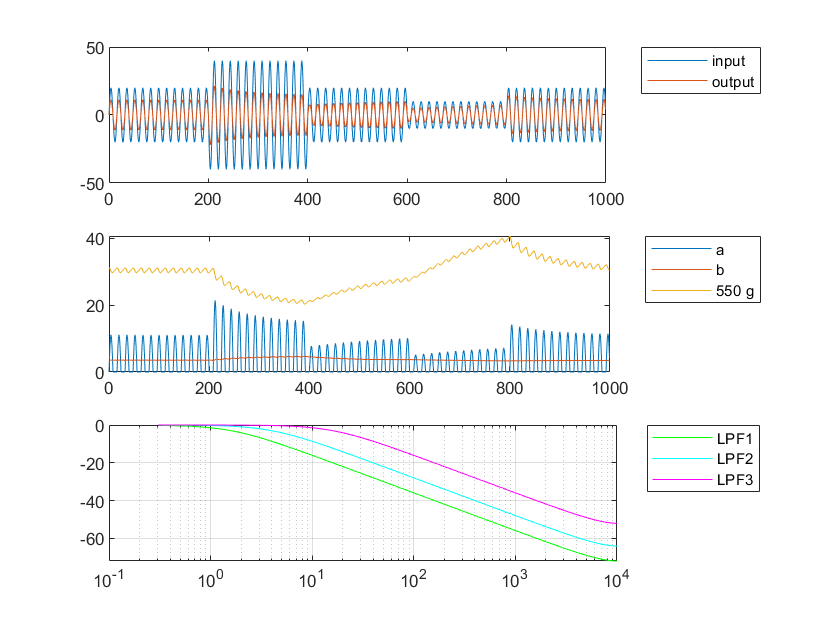

fig = fig + 1;

% Three stage AGC.
figure(fig);
all_sine_outs(:, fig) = plot_AGC(sine_in, sine_in_start, 10, hwr, ...
    [1 / (sr / 10), -2, 1; 1 / (sr / 25), -1, 2; 1 / (sr / 100), -1, 4]);

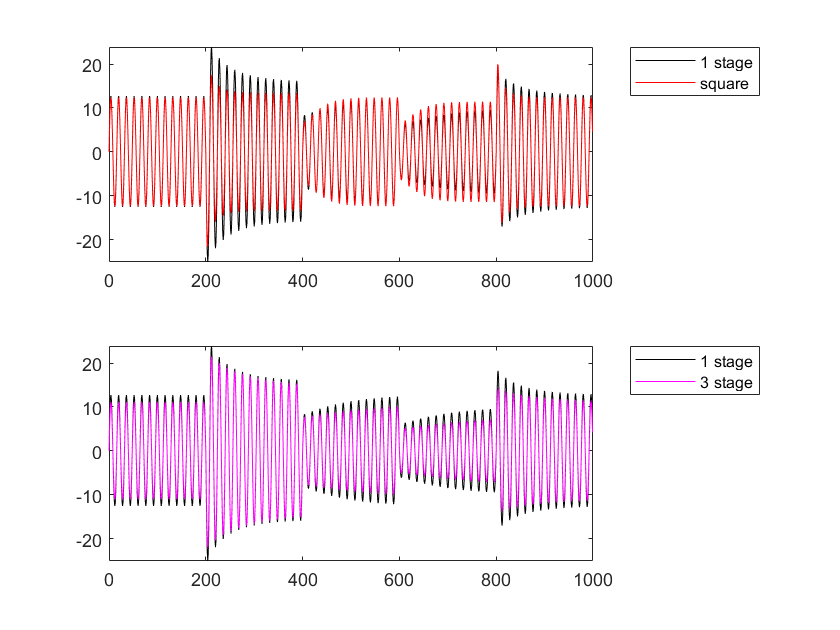

fig = fig + 1;

% Compare outputs
figure(fig);
subplot(2, 1, 1);
n = [0:size(all_sine_outs, 1)-1];
plot(n, all_sine_outs(:, 1), 'k', n, all_sine_outs(:, 2), 'r');
legend('1 stage', 'square', 'Location', 'NortheastOutside');
subplot(2, 1, 2);
plot(n, all_sine_outs(:, 1), 'k', n, all_sine_outs(:, 5), 'm');
legend('1 stage', '3 stage', 'Location', 'NortheastOutside');

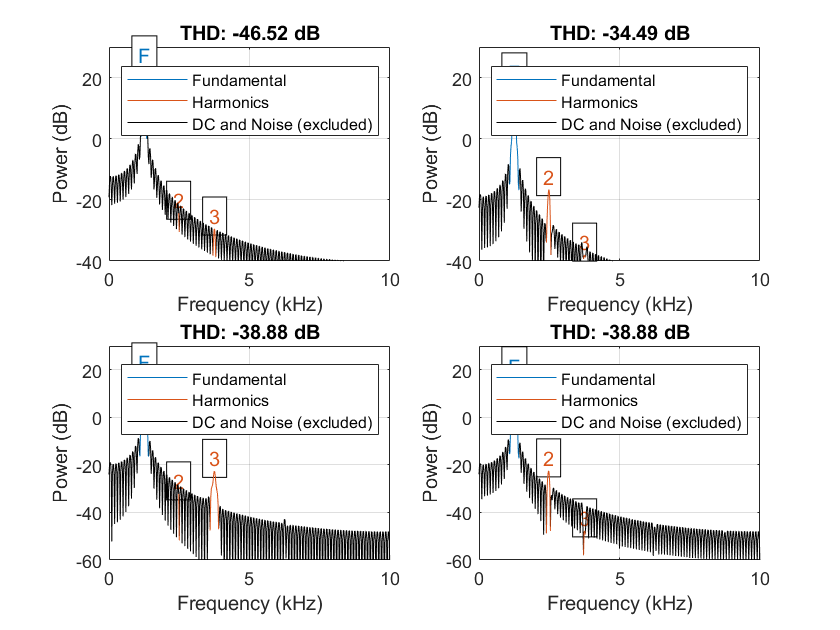

fig = fig + 1;

% Calculate and plot THD (dBc)
figure(fig);
Nharmonics = 3;
subplot(2, 2, 1);
thd(sine_in(sine_in_start:length(sine_in)), sr, Nharmonics);
subplot(2, 2, 2);
thd(all_sine_outs(:, 1), sr, Nharmonics);
subplot(2, 2, 3);
thd(all_sine_outs(:, 2), sr, Nharmonics);
subplot(2, 2, 4);
thd(all_sine_outs(:, 5), sr, Nharmonics);

function out = AGC(in, H, detector, lpfs, gains, gain_stages)
    global AGC_y_col AGC_a_col AGC_b_col AGC_g_col;
    out = zeros(length(in), 4);
    bs = zeros(length(in), length(lpfs));
    gs = zeros(length(in), length(gain_stages));
    out(1, AGC_b_col) = 0;
    for i = 1:length(gains)
        gs(1, i) = gain_stages(i) * gains{i}(bs(1, i));
    end
    out(1, AGC_g_col) = prod(gs(1, :));
    out(1, AGC_y_col) = H * in(1) * out(1, AGC_g_col);
    out(1, AGC_a_col) = detector(out(1, AGC_y_col));
    for t = 2:length(in)
        y = H * in(t) * out(t - 1, AGC_g_col);
        a = detector(y);
        for i = 1:length(gains)
            bs(t, i) = lpfs{i}(bs(t - 1, i), a);
            gs(t, i) = gain_stages(i) * gains{i}(bs(t, i));
        end
        out(t, AGC_g_col) = prod(gs(t, :));
        out(t, AGC_y_col) = y;
        out(t, AGC_a_col) = a;
        out(t, AGC_b_col) = max(bs(t, :));
    end
end

function out_signal = plot_AGC(signal, plot_start, H, detector, loop_params)
    global T;
    global Loop_omega_col Loop_K_col Loop_gain_col;
    lpfs = {};
    gains = {};
    lpfHs = {};
    for i = 1:size(loop_params, 1)
        omega = loop_params(i, Loop_omega_col);
        alpha = omega / (omega + 1);
        % Discrete Time Low Pass Filter
        lpfs{i} = @(y_n_1, x_n) y_n_1 + alpha * (x_n - y_n_1);
        [h, freq] = freqz([alpha], [1, alpha - 1], 32768, 1 / T);
        lpfHs{i} = h;
        % Gain Function
        K = loop_params(i, Loop_K_col);
        gains{i} = @(b) (1 - b / K) ^ K;
    end
    
    global AGC_y_col AGC_a_col AGC_b_col AGC_g_col;
    out_all = AGC(signal, H, detector, lpfs, gains, loop_params(:, Loop_gain_col));
    out = out_all(plot_start:size(out_all, 1), :);
    n = [0:size(out, 1)-1];
    subplot(3, 1, 1);
    out_signal = out(:, AGC_y_col);
    plot(n, signal(plot_start:length(signal)), n, out_signal);
    legend('input', 'output', 'Location', 'NortheastOutside');
    % Find the scale factor for 'g' so it's max = max(signal)
    g_factor = round(max(max(signal), max(out(:, AGC_a_col))) / max(out(:, AGC_g_col)) / 50) * 50;
    subplot(3, 1, 2);
    plot(n, out(:, AGC_a_col), n, out(:, AGC_b_col), n, g_factor * out(:, AGC_g_col));
    legend('a', 'b', strcat(int2str(g_factor), ' g'), 'Location', 'NortheastOutside');
    subplot(3, 1, 3);
    legends = {};
    lpf_colors = {'g', 'c', 'm', 'b', 'r', 'k'}; 
    for i = 1:length(lpfHs)
        semilogx(freq, 20 * log10(abs(lpfHs{i})), lpf_colors{i});
        legends{i} = strcat('LPF ', int2str(i));
        hold on;
    end
    hold off;
    grid on;
    legend(legends, 'Location', 'NortheastOutside');
end

% Prepare the AM sine signal as on the Fig. 11.9, with a priming intro.
function [signal, signal_start] = am_sine(freq, bAmp, mf, N, P)
    global T;
    % Stable Periods
    p = [bAmp * ones(P + 1, 1)', bAmp * mf, bAmp, bAmp / mf, bAmp];
    S = N / (length(p) - P);
    ampls = zeros(1, N + S * P);
    for i = 1:length(ampls)
        ampls(i) = p(fix((i - 1) / S) + 1);
    end
    signal = ampls .* sin([0:length(ampls)-1] * 2 * pi * freq * T);
    signal_start = S * P + 1;
end